ans = 11×2 table
    Time (s)    CoG (in from base of tank)
    ________    __________________________

        0                 15.037          
        1                 14.195          
        2                 13.411          
        3                 12.701          
        4                 12.089          
        5                 11.608          
        6                 11.308          
        7                 11.272          
        8                 11.636          
        9                 12.654          
       10                 14.851          


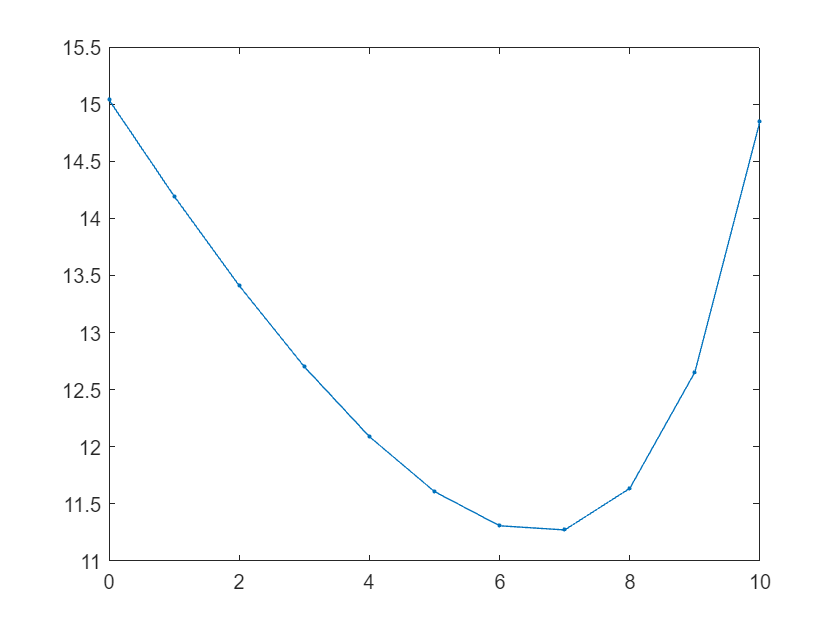

clear
clc

% Initializing variables
tL = 30.07; % Tank length
tR = 5.75; % Tank radius
wM = 25.5; % Wet mass
dM = 9.32; % Dry mass
time = 10; % Burn time
density = 0.04122124; % Propellant density (0.04 is for lox)

% Calling function
CoGs = getCoG(wM, dM, time, tL, tR, density);

function [CoGs] = getCoG(wM, dM, time, tL, tR, density)

%Vo = wM / density % Finds initial propellant volume
Vo = 781;
%mdot = wM/time % Finds mass flow rate
mdot = 2.5353160151;
tCG = dM * (tL/2); % Finds constant W1d1/tank term in COG equation

V = zeros(1,(round(time) + 1)); % Preallocates arrays for variables that change with time
mp = V;
d = V;
COG = V;
% Done preallocating (for now), it's loop time yippee
for t = (0:time)
    %V(t+1) = (mdot / density) * t; % Finds propellant volume at t
    mp(t+1) = wM - (mdot * t); % Finds propellant mass at t
    d(t+1) = ((Vo - ((mdot/density)*t)) / (2 * pi * ((5.75/2) ^ 2))); % Finds the distance term for the propellant at t
    %pCG = (mp(t+1) * d(t+1)); % Finds W2d2/propellant term in COG equation at t
    COG(t+1) = ((tCG + (mp(t+1) * d(t+1))) / (dM + mp(t+1))); % Finds (finally) the center of gravity at t
end
CoGs = zeros((round(time) + 1),2); % Preallocates space for CoGs table
CoGs(:,1) = 0:(round(time)); % Makes column of time values
CoGs(:,2) = COG; % Makes column of CoG values
array2table(CoGs,"VariableNames",{'Time (s)','CoG (in from base of tank)'}) % Makes CoG data prettier
tx = 0:(round(time));
plot(tx,COG,".-")
end